# KNN HOG

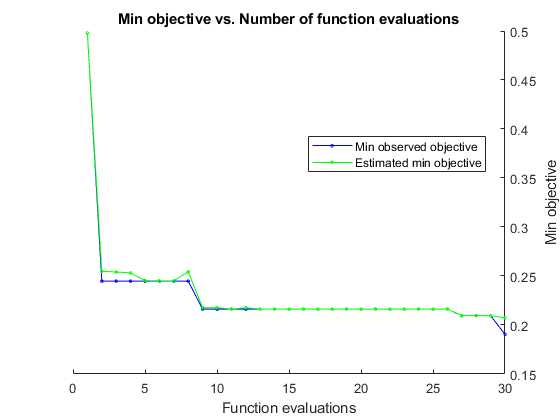

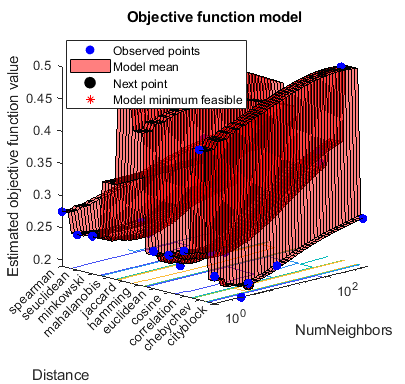

|=====================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   | NumNeighbors |     Distance |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |
|=====================================================================================================|
|    1 | Best   |      0.4981 |      4.3186 |      0.4981 |      0.4981 |          340 |    chebychev |
|    2 | Best   |     0.24476 |      5.2147 |     0.24476 |     0.25483 |            1 |   seuclidean |
|    3 | Accept |     0.45143 |      3.4244 |     0.24476 |     0.25411 |           13 |      hamming |
|    4 | Accept |     0.26286 |      5.8499 |     0.24476 |     0.25315 |          318 |   seuclidean |
|    5 | Accept |     0.27524 |      11.833 |     0.24476 |      0.2453 |            1 |     spearman |
|    6 | Accept |     0.24857 |      3.7899 |     0.24476 |     

classifier =   ClassificationKNN
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [F    M]
                       ScoreTransform: 'none'
                      NumObservations: 1050
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]
                             Distance: 'cityblock'
                         NumNeighbors: 4


  Properties, Methods


clc
clear 
close all

i = imageDatastore('New Data\*\*.png','LabelSource','foldernames');

tbl = countEachLabel(i);
minSetCount = min(tbl{:,2});
i = splitEachLabel(i, minSetCount, 'randomize');

i.ReadSize = 1500;
i.ReadFcn = @(loc)imresize(imread(loc),[128 , 128]);


[trainingSet, validationSet] = splitEachLabel(i, 0.7, 'randomize');

img = readimage(trainingSet, 206);
% % Extract HOG features and HOG visualization
[hog_8x8, vis8x8] = extractHOGFeatures(img,'CellSize',[8 8]);


cellSize = [8 8];
hogFeatureSize = length(hog_8x8);

numImages = numel(trainingSet.Files);
trainingFeatures = zeros(numImages, hogFeatureSize, 'single');

for i = 1:numImages
    img = readimage(trainingSet,i);
    trainingFeatures(i,:) = extractHOGFeatures(img,'CellSize',cellSize); 
end

% Get labels for each image.
trainingLabels = trainingSet.Labels;

% fitcecoc uses SVM learners and a 'One-vs-One' encoding scheme.
classifier = fitcknn(trainingFeatures, trainingLabels,'OptimizeHyperparameters','auto')


% Extract HOG features from the test set. The procedure is similar to what
% was shown earlier and is encapsulated as a helper function for brevity.
[testFeatures, testLabels] = helperExtractHOGFeaturesFromImageSet(validationSet,hogFeatureSize,cellSize);

% Make class predictions using the test features.
predictedLabels = predict(classifier, testFeatures);

% Tabulate the results using a confusion matrix.
confMat = confusionmat(testLabels, predictedLabels)

confMat =    190    35
    60   165


confMat = bsxfun(@rdivide,confMat,sum(confMat,2));

mean(diag(confMat))*100

ans = 78.8889

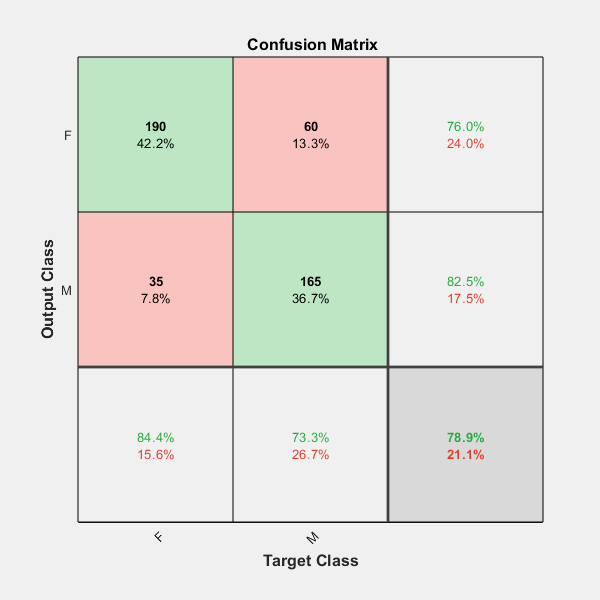

recall = zeros(2,1);
precision = zeros(2,1);
plotconfusion(testLabels, predictedLabels)

for i =1:size(confMat,1)
    recall(i)=confMat(i,i)/sum(confMat(i,:));
end
recall(isnan(recall))=[];
% Recall Calculation
Recall=(sum(recall)/size(confMat,1))*100
for i =1:size(confMat,1)
    precision(i)=confMat(i,i)/sum(confMat(:,i));
end
% Precision Calculation
Precision=(sum(precision)/size(confMat,1))*100
% F-score Calculation
F_score=(2*Recall*Precision/(Precision+Recall))

function [features, setLabels] = helperExtractHOGFeaturesFromImageSet(imds, hogFeatureSize, cellSize)
% Extract HOG features from an imageDatastore.

setLabels = imds.Labels;
numImages = numel(imds.Files);
features  = zeros(numImages, hogFeatureSize, 'single');

% Process each image and extract features
for j = 1:numImages
    img = readimage(imds, j);
    
    features(j, :) = extractHOGFeatures(img,'CellSize',cellSize);
end
end